% 
clc; 
clear; 
close all;

%importing of the Training Txt file 
engine1 = load("train_FD001.txt");

vars =["unit number","time in cycles","op setting 1","op setting 2","op setting 3","sensor measurement 1","sensor measurement 2","sensor measurement 3","sensor measurement 4","sensor measurement5","sensor measurement 6","sensor measurement 7","sensor measurement 8","sensor measurement 9","sensor measurement 10","sensor measurement 11","sensor measurement 12","sensor measurement 13","sensor measurement 14","sensor measurement 15","sensor measurement 16","sensor measurement 17","sensor_measurement 18","sensor measurement 19","sensor measurement 20","sensor measurement 21"];

Check for Misssing values

%checking for the missing values
missing_values = max(sum(ismissing(engine1)));
missing_values% there are no missing values

missing_values = 0

% changed the array to a table
engine1Table = array2table(engine1, 'VariableNames', vars);
engine1Table

engine1Table = 20631×26 table
    unit number    time in cycles    op setting 1    op setting 2    op setting 3    sensor measurement 1    sensor measurement 2    sensor measurement 3    sensor measurement 4    sensor measurement5    sensor measurement 6    sensor measurement 7    sensor measurement 8    sensor measurement 9    sensor measurement 10    sensor measurement 11    sensor measurement 12    sensor measurement 13    sensor measurement 14    sensor measurement 15    sensor measurement 16    sensor measurement 17    sensor_measurement 18    sensor measurement 19    sens

%since am using livescript, the summary function displays the summary quite
%well..and this can change 
summary(engine1Table)

Variables:

    unit number: 20631×1 double

        Values:

            Min           1   
            Median       52   
            Max         100   

    time in cycles: 20631×1 double

        Values:

            Min           1   
            Median      104   
            Max         362   

    op setting 1: 20631×1 double

        Values:

            Min       -0.0087 
            Median          0 
            Max        0.0087 

    op setting 2: 20631×1 double

        Values:

            Min       -0.0006 
            Median          0 
            Max        0.0006 

    op setting 3: 20631×1 double

        Values:

            Min         100   
            Median      100   
            Max         100   

    sensor measurement 1: 20631×1 double

        Values:

            Min        518.67 
            Median     518.67 
            Max        518.67 

    

To supplement the summary of our dataset

% for purposes of syncronizing, i have put most of the summary output in a
% table
for i = 1:length(engine1(1,:))
    Count(i) = nnz(~isnan(engine1(:,i)));
    Mean(i)  = mean(engine1(:,i));
    St.dev(i)    = std(engine1(:,i));
    Min(i)   = min(engine1(:,i));
    P25(i)   = prctile(engine1(:,i), 25);
    P50(i)   = prctile(engine1(:,i), 50);
    P75(i)   = prctile(engine1(:,i), 75);
    Max(i)   = max(engine1(:,i));
end

DataSummary     = table(Count', Mean', St.dev', Min', P25', P50', P75', Max', 'VariableNames', {'Count', 'Mean', 'St.dev', 'Min', 'P25', 'P50', 'P75', 'Max'}, ...
    'RowNames',vars)

DataSummary = 26×8 table
                             Count       Mean          St.dev        Min        P25       P50       P75       Max  
                             _____    ___________    __________    _______    _______    ______    ______    ______

    unit number              20631         51.507        29.228          1         26        52        77       100
    time in cycles           20631         108.81        68.881          1         52       104       156       362
    op setting 1             20631    -8.8701e-06     0.0021873    -0.0087    -0.0015         0    0.0015    0.0087
    op setting 2             20631     2.3508e-06    0

Lets Visualize some Variables Now

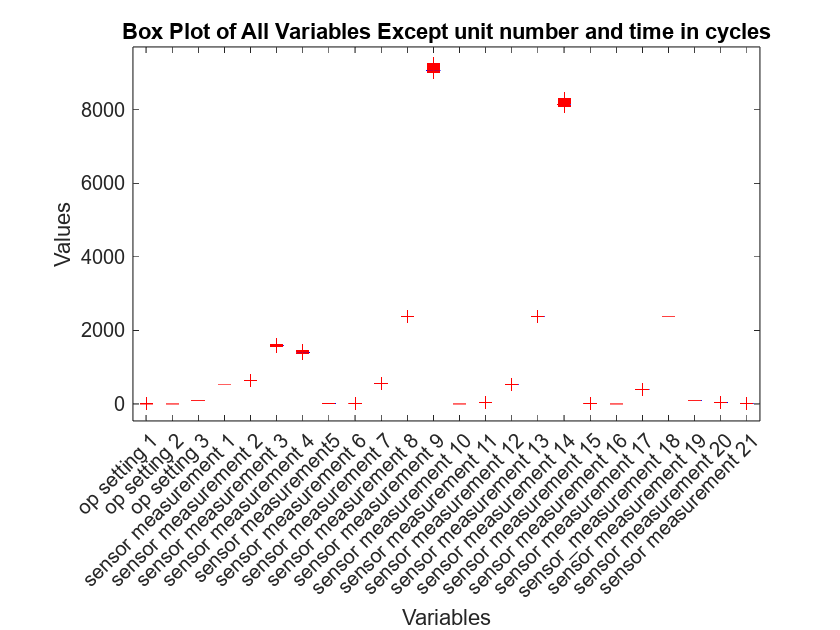


% box plot for all variables except unit_number and time_in_cycles
figure;
boxplot(engine1Table{:, 3:end}); % Excluding the first two columns
xlabel('Variables');
ylabel('Values');
title('Box Plot of All Variables Except unit number and time in cycles');
xticklabels(vars(3:end)); % Label x-axis with variable names
xtickangle(45); % for better readability

Lets also get an Understanding of the relationship between the variables and how they are correlated.

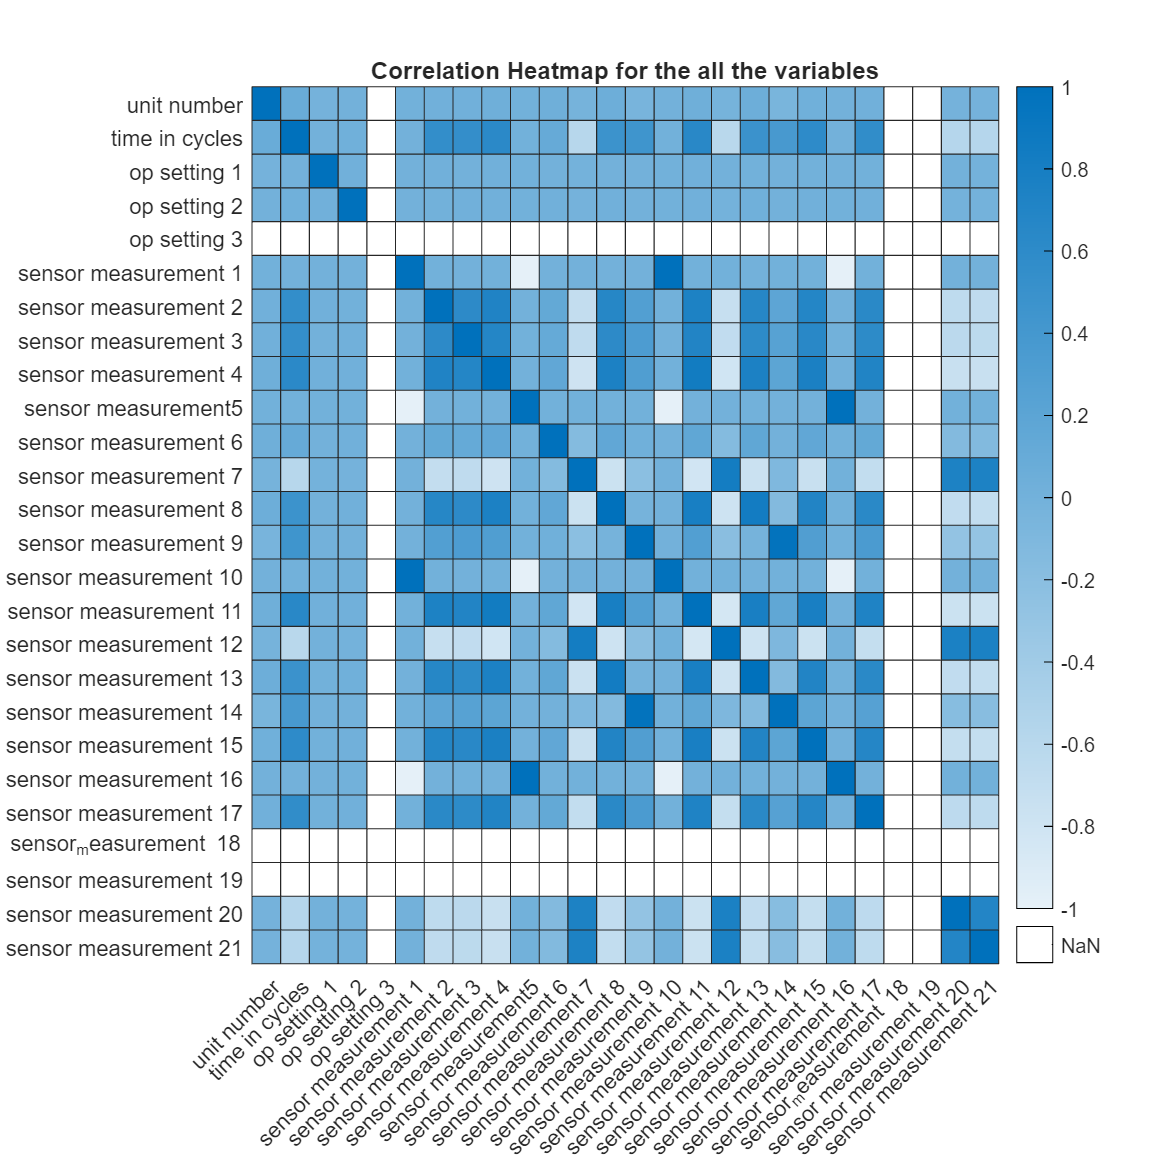

correlation = corr(engine1);

h = heatmap(correlation, 'MissingDataColor', 'w');
labels = vars;
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
title('Correlation Heatmap for the all the variables');
set(gcf, 'Position', [100, 100, 800, 800]);

From the above Data summary analysis, we can see that variable 5, 6, 10, 15, 21, 23, 24 have zero deviation, so 

they will not give us any important information going forward.

Also from the heatmap we can also observe that variable 3, 4, 11,23 and 24 donot correlate with any variable

engine1(:,[5,6,10,15,21,23,24])=[];
vars(:,[5,6,10,15,21,23,24])=[];

So variable 5,6,10,15,21,23,24 are then eliminated from our variables

engine1Table2 = array2table(engine1, 'VariableNames', vars);
engine1Table2

engine1Table2 = 20631×19 table
    unit number    time in cycles    op setting 1    op setting 2    sensor measurement 2    sensor measurement 3    sensor measurement 4    sensor measurement 6    sensor measurement 7    sensor measurement 8    sensor measurement 9    sensor measurement 11    sensor measurement 12    sensor measurement 13    sensor measurement 14    sensor measurement 15    sensor measurement 17    sensor measurement 20    sensor measurement 21
    ___________    ______________    ____________    ____________    ____________________    ____________________

We carry out another correlation Heat map and try to see which variables will still be correlated.

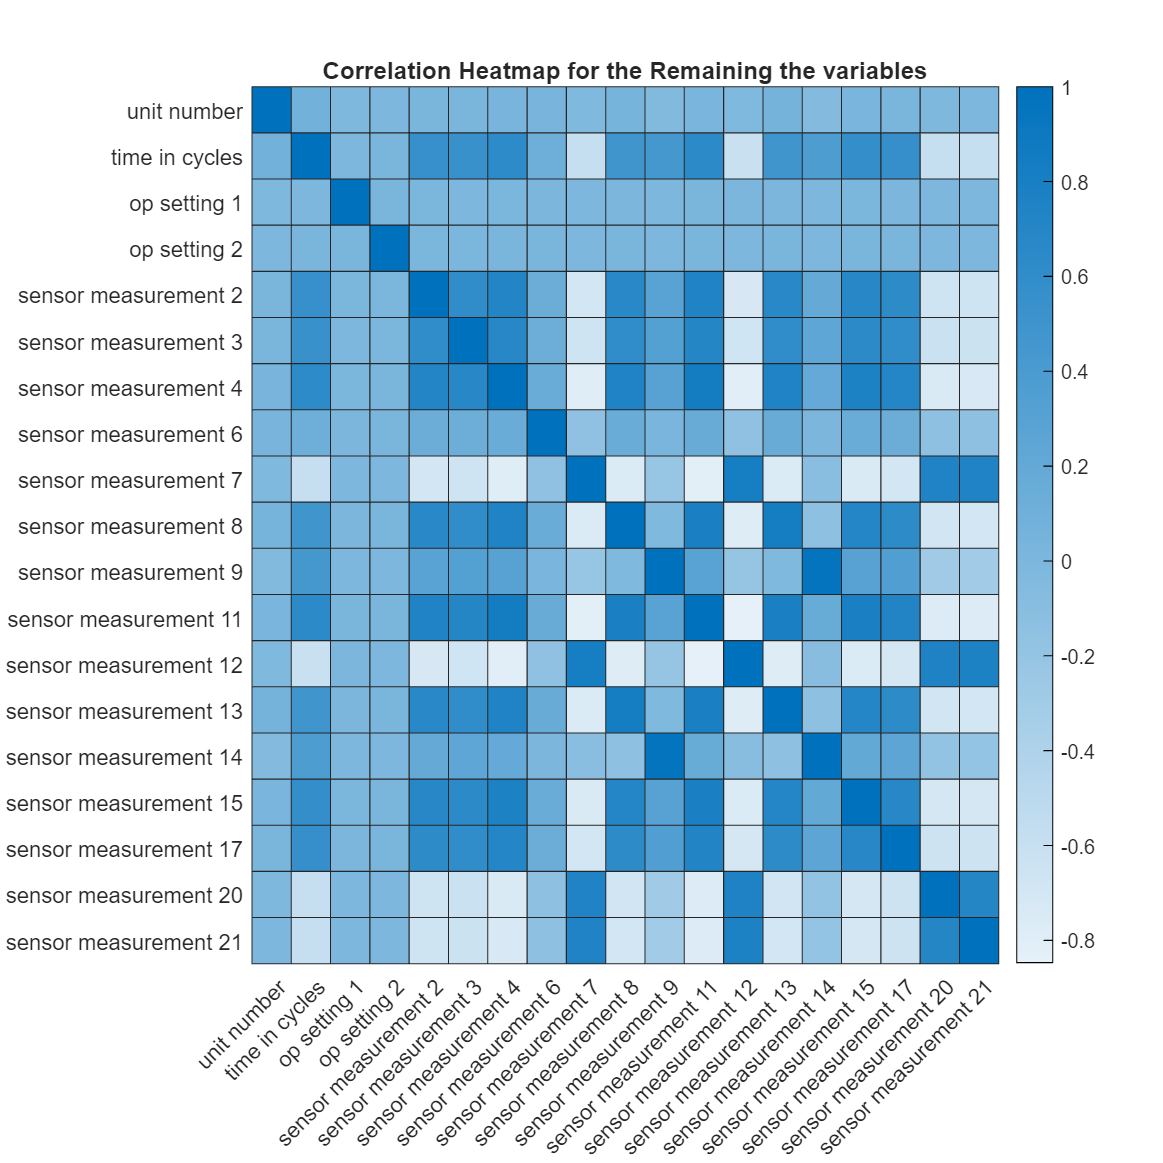

correlation = corr(engine1);
h = heatmap(correlation, 'MissingDataColor', 'w');
labels = vars;
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
title('Correlation Heatmap for the Remaining the variables');

From the Heat map, We can again see that Variable 1,3,4, and 8 are not correlated with any variable and therefore will not give us any new information.

engine1(:,[1,3,4,8])=[];
vars(:,[1,3,4,8])=[];
engine1Table2 = array2table(engine1, 'VariableNames', vars);
engine1Table2

engine1Table2 = 20631×15 table
    time in cycles    sensor measurement 2    sensor measurement 3    sensor measurement 4    sensor measurement 7    sensor measurement 8    sensor measurement 9    sensor measurement 11    sensor measurement 12    sensor measurement 13    sensor measurement 14    sensor measurement 15    sensor measurement 17    sensor measurement 20    sensor measurement 21
    ______________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    _____________________    ________________


correlation = corr(engine1);
h = heatmap(correlation, 'MissingDataColor', 'w');
labels = vars;
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
title('Correlation Heatmap for the Remaining the variables');

## **PCA**

## **Division of data into calibration, validation and test partitions**

r1       = length(engine1);
cv      = cvpartition(r1, 'Holdout', 0.3);

% Data is divided into training and test data.
calibrate_idx = cv.training(1);
test_idx = cv.test(1);
sum(calibrate_idx);
sum(test_idx);

## Scalling and Centering of the data.

X = engine1;
Model_calibration = zscore(X(calibrate_idx, :)); 

% PCA

[loading, T, latent, t2, explained] = pca(Model_calibration, 'Centered', false);

## **Explanation of Variance per Principal Component**

figure;
pareto(explained)
xlabel('Principal Components')
ylabel('Variance Explained')
title('Pareto Graph explaining the Variance contributed by each Principal Component')

## Lets also see the contribution of Variance from the 15 Variables in PC 1 and 2

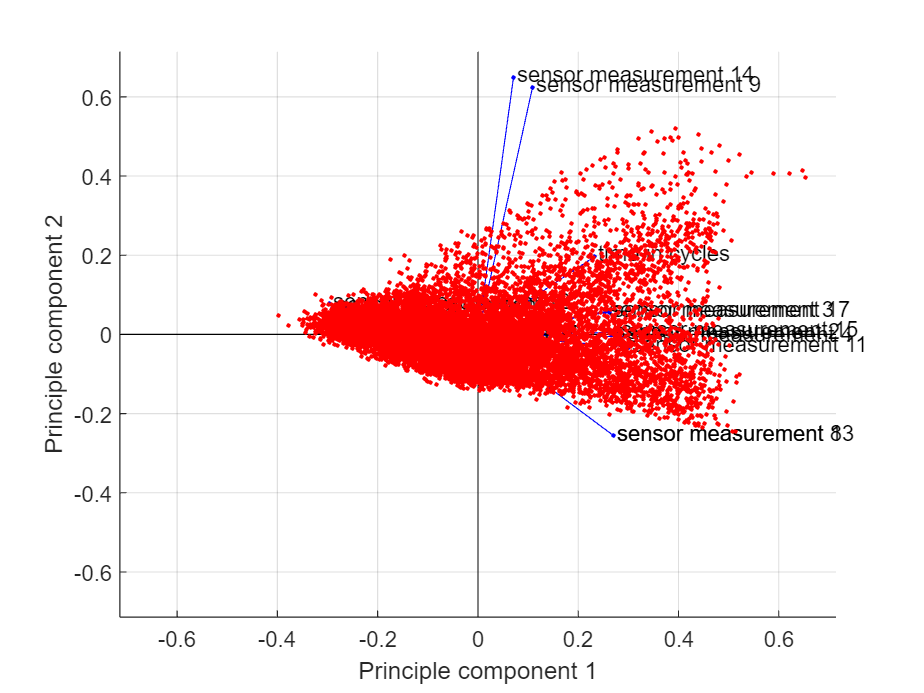

figure; 

biplot(loading(:,1:2), 'Scores', T(:,1:2), 'VarLabels', vars);
xlabel("Principle component 1");
ylabel("Principle component 2");

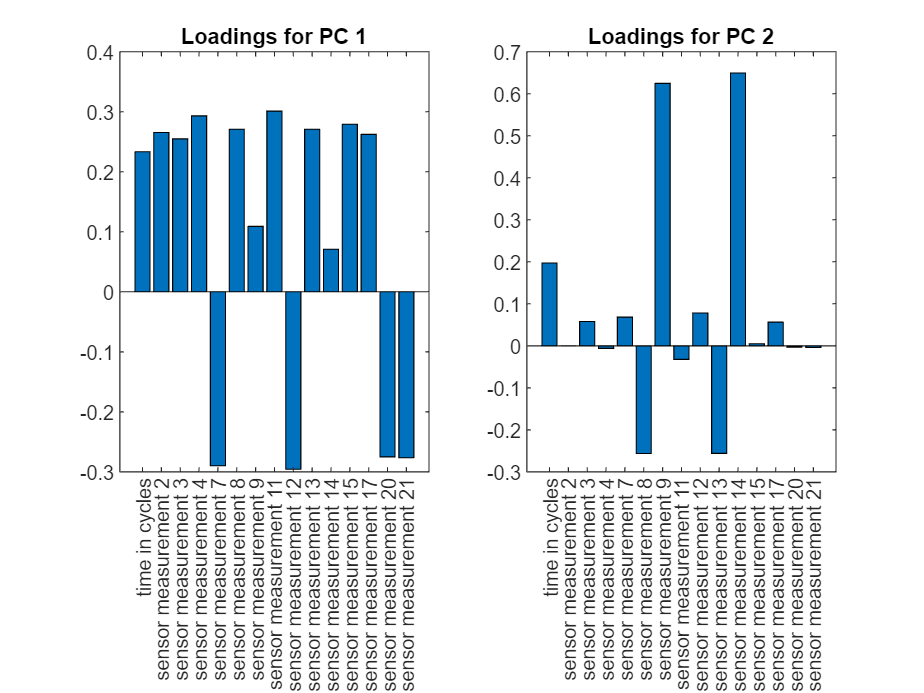

figure;
subplot(1,2,1);
    bar(loading(:,1)); %Loadings bar plot
    xticklabels(vars);
    title("Loadings for PC 1");

subplot(1,2,2);
    bar(loading(:,2)); %Loadings bar plot
    xticklabels(vars);
    title("Loadings for PC 2");